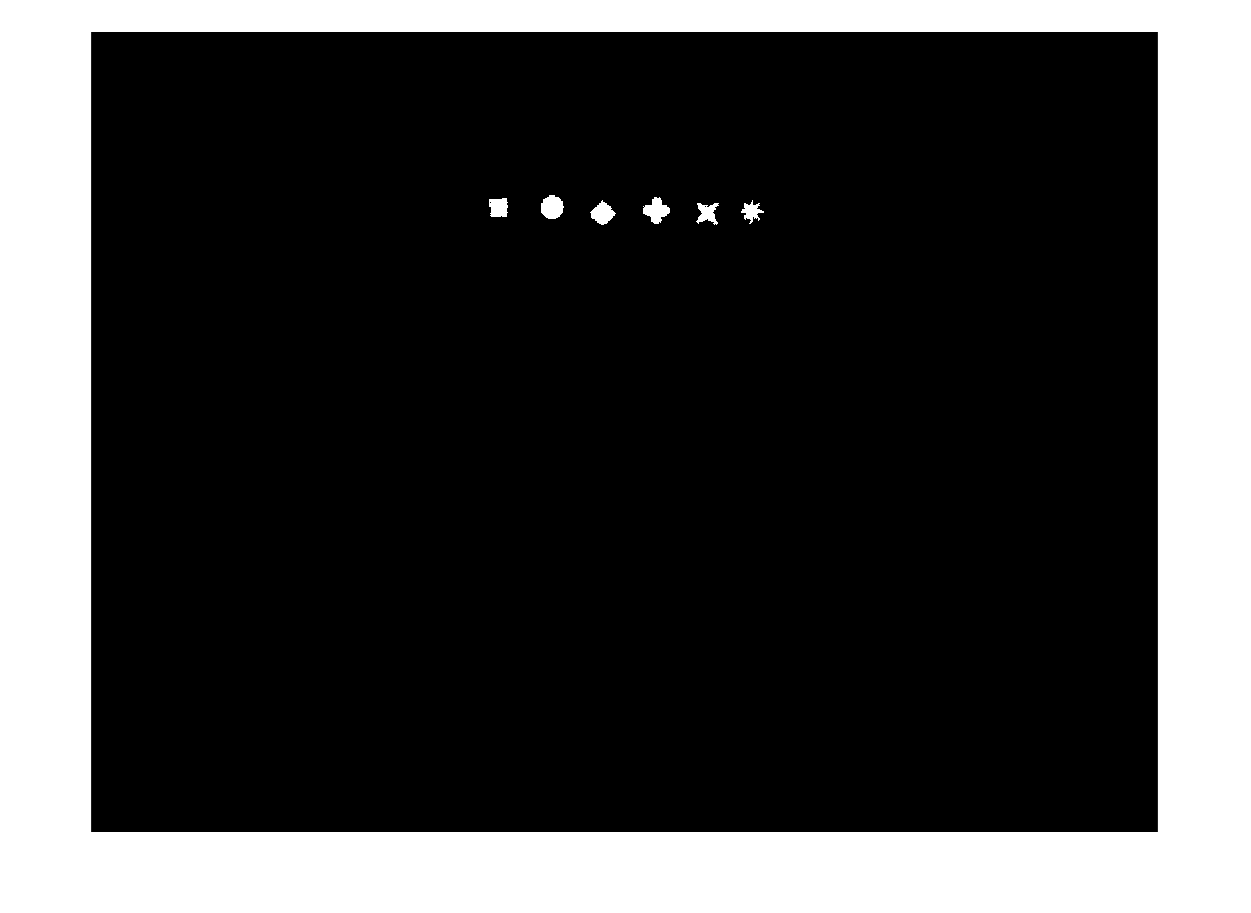

Red = 1.1;
Green = 1.2;
Blue = 1.3;
Yellow = 1.4;

Circle = 2.1;
Flower = 2.2;
Diamond = 2.3;
Square = 2.4;
star4 = 2.5;
star6 = 2.6;

conveyorImg = imread('Assignment_2_Test_Pics\conveyor_AllShapes2.jpg');

% extract colours
[conveyorImgRBW,conveyorImgRed] = createConveyorRedMask(conveyorImg);
[conveyorImgGBW,conveyorImgGreen] = createConveyorGreenMask(conveyorImg);
[conveyorImgBBW,conveyorImgBlue] = createConveyorBlueMask(conveyorImg);
[conveyorImgYBW,conveyorImgYellow] = createConveyorYellowMask(conveyorImg);

% remove any white noise from all the masks
conveyorImgRBW = bwareaopen(conveyorImgRBW,450);  
conveyorImgGBW = bwareaopen(conveyorImgGBW,450); 
conveyorImgBBW = bwareaopen(conveyorImgBBW,450); 
conveyorImgYBW = bwareaopen(conveyorImgYBW,450); 

conveyorImgRBW = removeWhiteNoiseByArea(conveyorImgRBW);
conveyorImgGBW = removeWhiteNoiseByArea(conveyorImgGBW);
conveyorImgBBW = removeWhiteNoiseByArea(conveyorImgBBW);
conveyorImgYBW = removeWhiteNoiseByArea(conveyorImgYBW);

conveyorImgRBW = removeWhiteNoiseByMajorAxis(conveyorImgRBW);
conveyorImgGBW = removeWhiteNoiseByMajorAxis(conveyorImgGBW);
conveyorImgBBW = removeWhiteNoiseByMajorAxis(conveyorImgBBW);
conveyorImgYBW = removeWhiteNoiseByMajorAxis(conveyorImgYBW);

conveyorImgRBW = removeWhiteNoiseByMinorAxis(conveyorImgRBW);
conveyorImgGBW = removeWhiteNoiseByMinorAxis(conveyorImgGBW);
conveyorImgBBW = removeWhiteNoiseByMinorAxis(conveyorImgBBW);
conveyorImgYBW = removeWhiteNoiseByMinorAxis(conveyorImgYBW);

imshow(conveyorImgRBW);

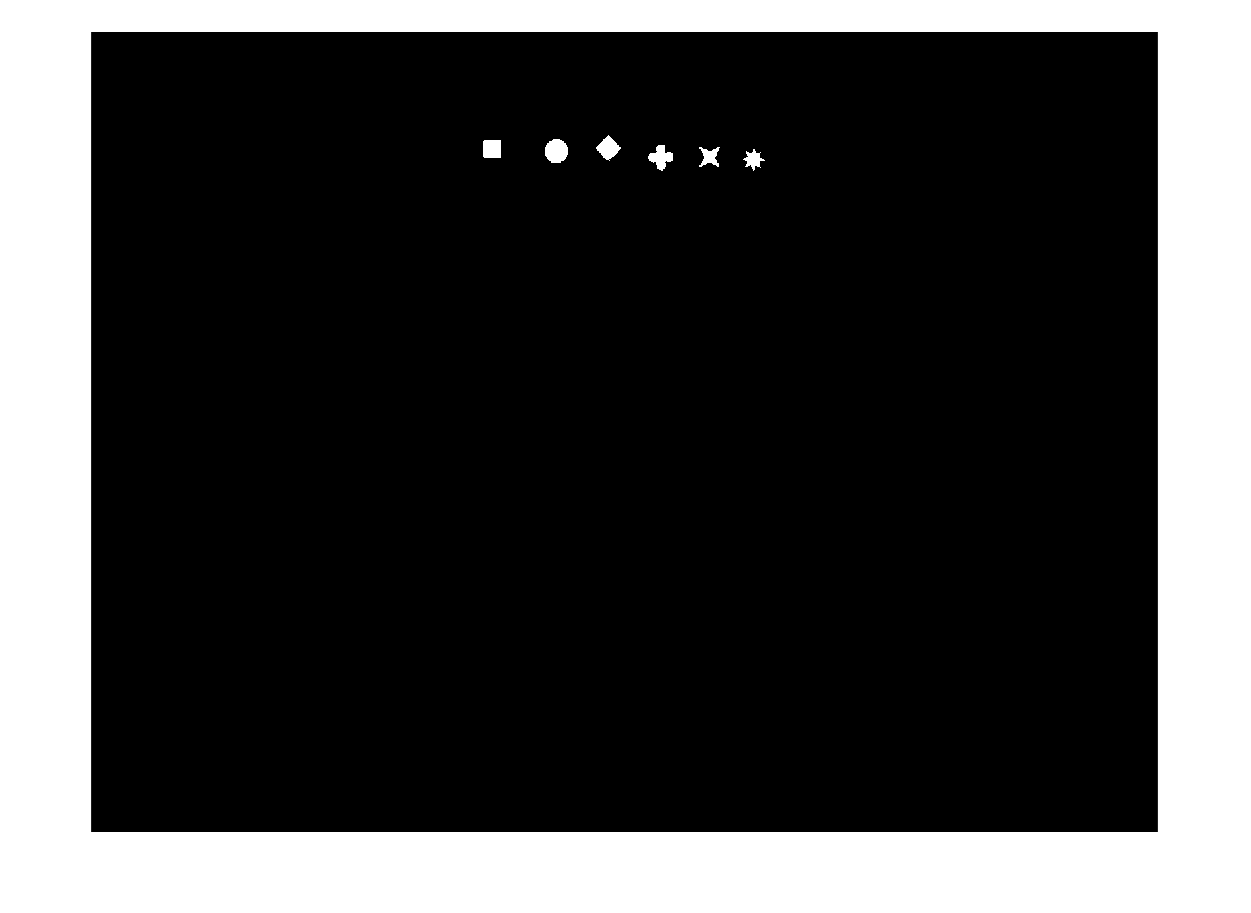

imshow(conveyorImgGBW);

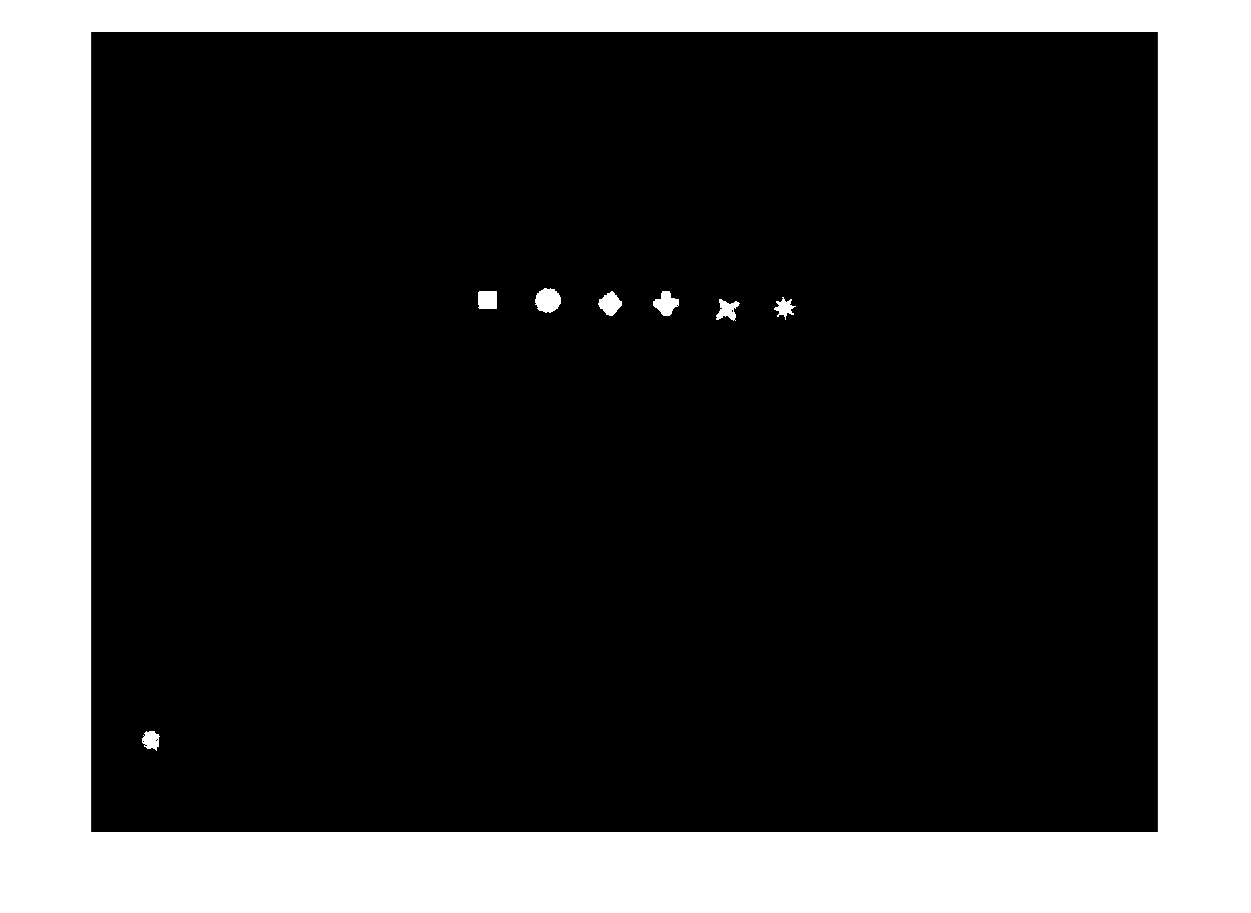

imshow(conveyorImgBBW);

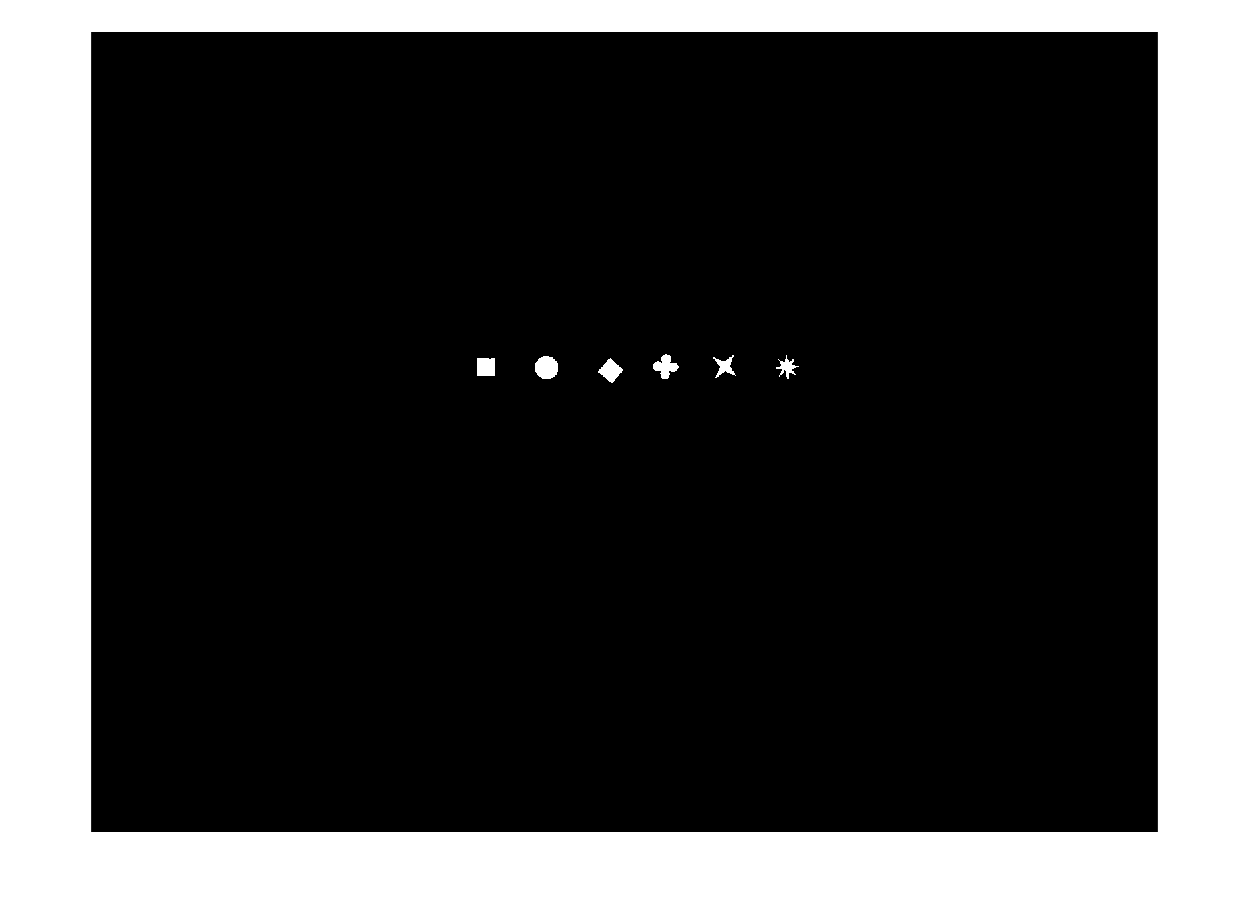

imshow(conveyorImgYBW);


% determine if the colour red, green, blue or yellow exists
redExist = find(conveyorImgRBW);
greenExist = find(conveyorImgGBW);
blueExist = find(conveyorImgBBW);
yellowExist = find(conveyorImgYBW);

% determine colour of the block
if length(yellowExist) > 10
    display("It's a yellow block");
    blockColour = Yellow;    
    blockImgBW = conveyorImgYBW;
    
elseif length(redExist) > 10
    display("It's a red block");
    blockColour = Red;
    
elseif length(greenExist) > 10
    display("It's a green block");
    blockColour = Green;
    
elseif length(blueExist) > 10
    display("It's a blue block");
    blockColour = Blue;
end

    "It's a yellow block"




% ---------------------------------------------------------------------
%% FOR TESTING PURPOSES: leave only one shape from the multiple shapes
s = regionprops(blockImgBW,'Area', 'BoundingBox');
areas = vertcat(s.Area);
bbox = vertcat(s.BoundingBox);

xCorner = bbox(:,1);
yCorner = bbox(:,2);
width = bbox(:,3);
height = bbox(:,4);

%% Drawing boxes 
xmin = xCorner;
ymin = yCorner;
xmax = xmin + width - 1;
ymax = ymin + height - 1;
% Expand the bounding boxes by a small amount.
expansionAmount = 0.02;
xmin = (1-expansionAmount) * xmin;
ymin = (1-expansionAmount) * ymin;
xmax = (1+expansionAmount) * xmax;
ymax = (1+expansionAmount) * ymax;
% Clip the bounding boxes to be within the image bounds
xmin = max(xmin, 1);
ymin = max(ymin, 1);
xmax = min(xmax, size(blockImgBW,2));
ymax = min(ymax, size(blockImgBW,1));

%removeIdx = find (areas ~= 964); % circle
%removeIdx = find (areas ~= 774); % flower
%removeIdx = find (areas ~= 754); % Diamond
%removeIdx = find (areas ~= 724); % Square
%removeIdx = find (areas ~= 501); % 4star
removeIdx = find (areas ~= 459); % 6star

% make the rest of the shapes black
for l = 1: length(removeIdx)
    blockImgBW(round(ymin(removeIdx(l))):round(ymax(removeIdx(l))), ...
        round(xmin(removeIdx(l))):round(xmax(removeIdx(l)))) = 0;
end

% ---------------------------------------------------------------------
%% Grab the property of the shape
shpSts = regionprops(blockImgBW, 'Area', 'Eccentricity', 'Extent',...
    'Perimeter', 'Centroid', 'ConvexArea');
area = vertcat(shpSts.Area);
eccentricity = vertcat(shpSts.Eccentricity); 
extent = vertcat(shpSts.Extent);
perimeter = vertcat(shpSts.Perimeter);
centroid = vertcat(shpSts.Centroid);
convexArea = vertcat(shpSts.ConvexArea);

if area > 950
    display("It's a circle");
    shape = Circle;
elseif area > 700
    if extent > 0.9
        display("It's a Square");
        shape = Square;
    elseif convexArea > 940
        display("It's a Flower");
        shape = Flower;
    else 
        display("It's a Diamond");
        shape = Diamond;
    end
else
    if convexArea > 900
        display("It's a 4star");
        shape = star4;
    else 
        display("It's a 6star");
        shape = star6;
    end
end

    "It's a 6star"




figure();
imshow(blockImgBW); hold on;

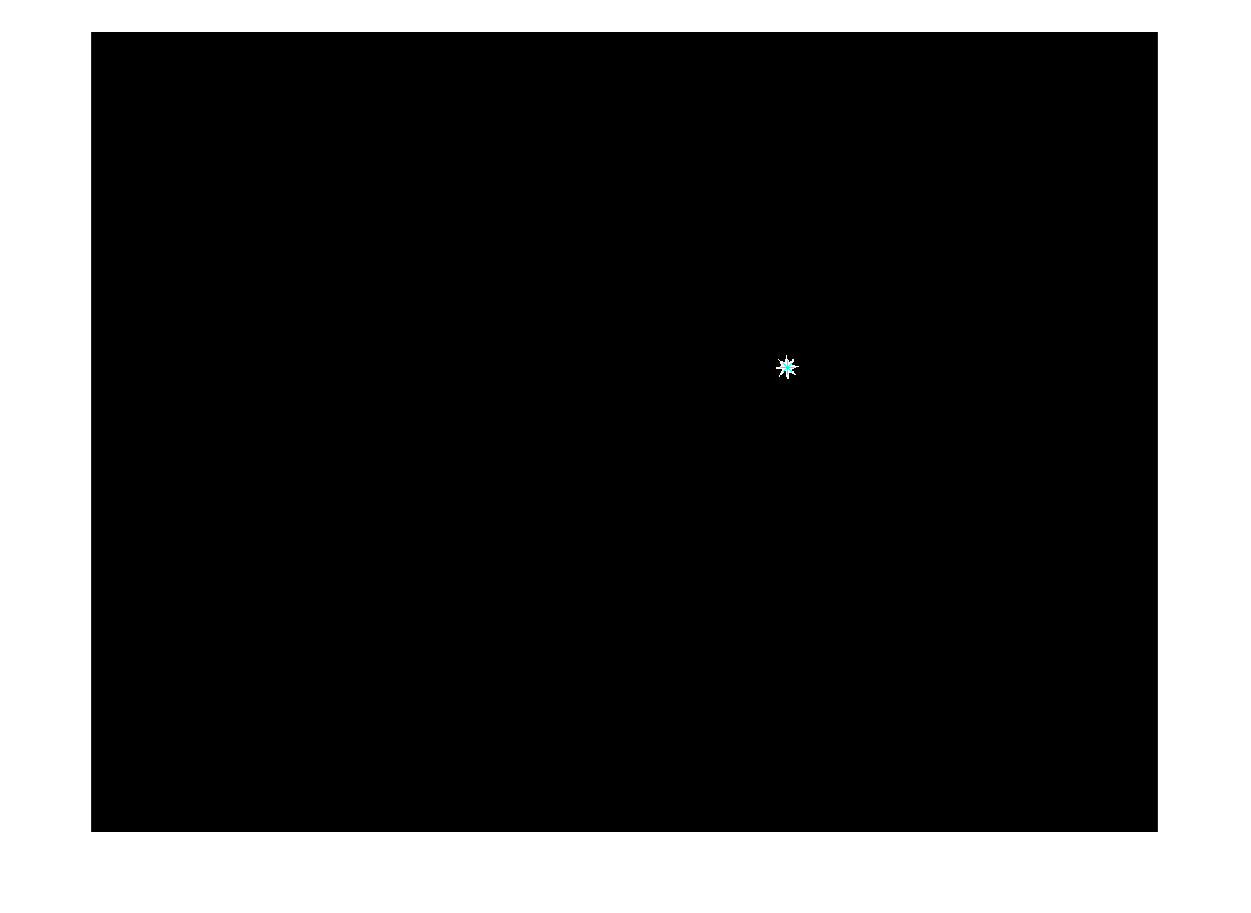

plot(centroid(1), centroid(2), 'c*', 'MarkerSize', 8); 
hold off;



%}

## Other functions

function centroids = extractCentroids(conveyorImgBW)
    s = regionprops(conveyorImgBW, 'Centroid');
    centroids = vertcat(s.Centroid);
    figure()
    imshow(conveyorImgBW);
    hold on;
    plot(centroids(:,1), centroids(:,2), 'c*', 'MarkerSize', 8);
    hold off;
end


function conveyorImgBW = removeWhiteNoiseByArea(conveyorImgBW)
    % remove unwanted noise based on area found by region props
    
    s = regionprops(conveyorImgBW, 'Area', 'BoundingBox');
    %imshow(conveyorImgBW);
    
    % store all values
    bbox = vertcat(s.BoundingBox);
    areas = vertcat(s.Area);
    
    xCorner = bbox(:,1);
    yCorner = bbox(:,2);
    width = bbox(:,3);
    height = bbox(:,4);
    
    %% Drawing boxes 
    xmin = xCorner;
    ymin = yCorner;
    xmax = xmin + width - 1;
    ymax = ymin + height - 1;
    % Expand the bounding boxes by a small amount.
    expansionAmount = 0.02;
    xmin = (1-expansionAmount) * xmin;
    ymin = (1-expansionAmount) * ymin;
    xmax = (1+expansionAmount) * xmax;
    ymax = (1+expansionAmount) * ymax;
    % Clip the bounding boxes to be within the image bounds
    xmin = max(xmin, 1);
    ymin = max(ymin, 1);
    xmax = min(xmax, size(conveyorImgBW,2));
    ymax = min(ymax, size(conveyorImgBW,1));
    
    % find the letters using their specific areas
    removeIdx = find(areas > 1200 | areas < 400);
    
    % make the noise dark
    for l = 1: length(removeIdx)
        conveyorImgBW(round(ymin(removeIdx(l))):round(ymax(removeIdx(l))), round(xmin(removeIdx(l))):round(xmax(removeIdx(l)))) = 0;
    end

%figure();
%imshow(conveyorImgBW)
end

function conveyorImgBW = removeWhiteNoiseByMajorAxis(conveyorImgBW)
    % remove unwanted noise based on area found by region props
    
    s = regionprops(conveyorImgBW, 'MajorAxisLength', 'BoundingBox');
    %imshow(conveyorImgBW);
    
    % store all values
    bbox = vertcat(s.BoundingBox);
    majorAxis = vertcat(s.MajorAxisLength);
    
    xCorner = bbox(:,1);
    yCorner = bbox(:,2);
    width = bbox(:,3);
    height = bbox(:,4);
    
    %% Drawing boxes 
    xmin = xCorner;
    ymin = yCorner;
    xmax = xmin + width - 1;
    ymax = ymin + height - 1;
    % Expand the bounding boxes by a small amount.
    expansionAmount = 0.02;
    xmin = (1-expansionAmount) * xmin;
    ymin = (1-expansionAmount) * ymin;
    xmax = (1+expansionAmount) * xmax;
    ymax = (1+expansionAmount) * ymax;
    % Clip the bounding boxes to be within the image bounds
    xmin = max(xmin, 1);
    ymin = max(ymin, 1);
    xmax = min(xmax, size(conveyorImgBW,2));
    ymax = min(ymax, size(conveyorImgBW,1));
    
    % find the letters using their specific areas
    removeIdx = find(majorAxis > 40 | majorAxis < 25);
    
    % make the noise dark
    for l = 1: length(removeIdx)
        conveyorImgBW(round(ymin(removeIdx(l))):round(ymax(removeIdx(l))), round(xmin(removeIdx(l))):round(xmax(removeIdx(l)))) = 0;
    end
    
    %figure();
    %imshow(conveyorImgBW)
end

function conveyorImgBW = removeWhiteNoiseByMinorAxis(conveyorImgBW)
% remove unwanted noise based on area found by region props
    
s = regionprops(conveyorImgBW, 'MinorAxisLength', 'BoundingBox');
%imshow(conveyorImgBW);

% store all values
bbox = vertcat(s.BoundingBox);
minorAxis = vertcat(s.MinorAxisLength);

xCorner = bbox(:,1);
yCorner = bbox(:,2);
width = bbox(:,3);
height = bbox(:,4);

%% Drawing boxes 
xmin = xCorner;
ymin = yCorner;
xmax = xmin + width - 1;
ymax = ymin + height - 1;
% Expand the bounding boxes by a small amount.
expansionAmount = 0.02;
xmin = (1-expansionAmount) * xmin;
ymin = (1-expansionAmount) * ymin;
xmax = (1+expansionAmount) * xmax;
ymax = (1+expansionAmount) * ymax;
% Clip the bounding boxes to be within the image bounds
xmin = max(xmin, 1);
ymin = max(ymin, 1);
xmax = min(xmax, size(conveyorImgBW,2));
ymax = min(ymax, size(conveyorImgBW,1));

% find the letters using their specific areas
removeIdx = find(minorAxis > 40 | minorAxis < 25);

% make the noise dark
for l = 1: length(removeIdx)
    conveyorImgBW(round(ymin(removeIdx(l))):round(ymax(removeIdx(l))), round(xmin(removeIdx(l))):round(xmax(removeIdx(l)))) = 0;
end

%figure();
%imshow(conveyorImgBW)
end